clc;clear;close all;

## 生成点

warning off

x = [-0.17263699	0.64102824	0.619187272	-0.169604585	-0.172290695	0.640753956	0.621242344	-0.170769907	-0.171522965	0.640246152	0.624506602	-0.171830944	-0.17083717	0.639008371	0.628110178	-0.171314854];
y = [0.018979904	0.142571117	0.609214188	0.276047528	-0.053249894	-0.032656584	0.438329502	0.208959385	-0.125595109	-0.206542736	0.267949915	0.140160375	-0.198118165	-0.378594402	0.096932468	0.069163785];
z = [-0.344388792	-0.670489171	0.286631526	0.1830114	-0.309268295	-0.580626074	0.372157833	0.220360057	-0.273244453	-0.491250982	0.458562455	0.258402244	-0.237311062	-0.402116506	0.545590665	0.294559421];


azimuth = 5.819341;
elevation = 1.582673;

P1 = [-0.25222006 0.655135248 -0.327650295];
P2 = [-0.249753513 -0.390018781 0.195244076];

xx = [-0.166541824	-0.143183482	0.086083038	0.156469149	0.466618822	0.56448817	0.839716947	0.807804096];
yy = [-0.049231542	0.233661612	-0.104236007	0.34170614	-0.091332629	0.380144412	0.261440943	0.017627278];
zz = [0.365326614	-0.524532874	0.659289339	-0.829545167	0.707237057	-0.813472591	-0.522760129	0.428110448];
PointFC = [xx;yy;zz];
Points = [x;y;z];
Points = [Points,PointFC];

PAB = Points(:,5);

## 拟合圆柱

[Mcenter,MTaon,Mradial,Err_every,Bottom_round_center1,Bottom_round_center2]=Calculate_accurate_cylinders_from_multiple_measurement_points2(Points,P1,P2);

## A、B面点测试

numShengLu = 4;
phi = pi/4;

toff = zeros(1,2*numShengLu);
roff = zeros(1,2*numShengLu);

Ang = ShengLuJiaoJiSuan(numShengLu)

Ang =     0.9425    0.3142   -0.3142   -0.9425   -0.9425   -0.3142    0.3142    0.9425



[PointTable_A_off,PointTable_B_off] = Calculat_A_and_B_Points_after_Offest2(MTaon',Mcenter',Mradial,PAB,phi,Ang,toff,roff)

PointTable_A_off =    -0.1388    0.1606    0.5321    0.8340    0.8380    0.5387    0.1671   -0.1347
    0.2342    0.3332    0.3381    0.2470   -0.0606   -0.1596   -0.1645   -0.0734
   -0.5243   -0.8182   -0.8182   -0.5243    0.4268    0.7207    0.7207    0.4268


PointTable_B_off =    -0.1305    0.1739    0.5455    0.8422    0.8297    0.5253    0.1537   -0.1430
   -0.3951   -0.6850   -0.6801   -0.3823    0.5687    0.8586    0.8537    0.5559
   -0.2026   -0.2976   -0.2976   -0.2026    0.1051    0.2001    0.2001    0.1051


## 绘图验证

figure
hold on
% 绘制圆柱面
plotcylinder(Bottom_round_center1,Bottom_round_center2,'black',Mradial,0.2)
xlabel('x')
ylabel('y')
zlabel('z')
axis equal
camlight;
lighting flat;

% 绘制散点
scatter3(Points(1,:),Points(2,:),Points(3,:),5,"filled");
scatter3([P1(1),P2(1)],[P1(2),P2(2)],[P1(3),P2(3)],10,"filled");

PointTable_A_off = PointTable_A_off';
PointTable_B_off = PointTable_B_off';
scatter3(PointTable_A_off(:,1),PointTable_A_off(:,2),PointTable_A_off(:,3),20,'filled','yellow')
scatter3(PointTable_B_off(:,1),PointTable_B_off(:,2),PointTable_B_off(:,3),20,'filled','yellow')

## 复测数据

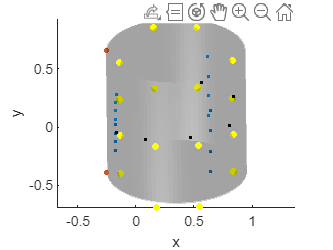

xx = [-0.166541824	-0.143183482	0.086083038	0.156469149	0.466618822	0.56448817	0.839716947	0.807804096];
yy = [-0.049231542	0.233661612	-0.104236007	0.34170614	-0.091332629	0.380144412	0.261440943	0.017627278];
zz = [0.365326614	-0.524532874	0.659289339	-0.829545167	0.707237057	-0.813472591	-0.522760129	0.428110448];
PointFC = [xx;yy;zz];

scatter3(xx,yy,zz,5,'filled','black')

## 计算距离

[Distance,theta,LTPY,TiC,Wquanzhong1,Wquanzhong2]=YuanXingFuCe(PointFC,numShengLu,Mcenter,MTaon,Mradial,phi)

Distance =     0.9340    1.5558    1.5951    0.9821


theta =     2.3504    2.3326    2.3411    0.8482


LTPY =     0.0158    0.0186   -0.0137    0.0005


TiC =    -0.9776   -0.5804   -0.7040   -0.0097    0.1350    0.6490    0.9597    0.5117


Wquanzhong1 =     0.0816
    0.0816
    0.5641
    0.5641
    0.9885
    0.9885
    0.6175
    0.6175


Wquanzhong2 =     0.0300
    0.0300
    0.5903
    0.5903
    0.9711
    0.9711
    0.7187
    0.7187
